clear; clc;

% --- Parameters ---
data_folder = '/Users/manoharpaturi/Desktop/EEE S2 Proj/TestCasesLibrary_Measurement/Forced oscillation/Case 1F';
dt = 40 / 1200; % Time step (s)
expected_gens = 29; % Expected number of generators
fixed_rank = 29; % Force 29 modes
reg_param = 1e-2; % Regularization parameter for DMD

% --- Load Data ---
try
    [Xraw, num_gens] = load_data(data_folder, dt);
    if num_gens ~= expected_gens
        error('Number of generators (%d) does not match expected (%d).', num_gens, expected_gens);
    end
    fprintf('Number of generators: %d\n', num_gens);
catch e
    error('Failed to load data: %s', e.message);
end

Raw data size for rotor_speeds.csv: 1201 rows, 29 columns
Loaded rotor_speeds.csv: 1201 rows, 29 columns
Raw data size for rotor_angles.csv: 1201 rows, 29 columns
Loaded rotor_angles.csv: 1201 rows, 29 columns
Final Xraw: 29 signals, 2402 time steps


Number of generators: 29



% --- Prepare DMD Inputs ---
Xraw = Xraw - mean(Xraw, 2); % Remove mean
X1 = Xraw(:, 1:end-1); % Snapshot t
X2 = Xraw(:, 2:end); % Snapshot t+1
t = (0:size(Xraw, 2)-1) * dt; % Time vector

% --- Rank Selection ---
try
    [U, S, V] = svd(X1, 'econ');
    singular_values = diag(S);
    r = min(fixed_rank, length(singular_values));
    if r < fixed_rank
        warning('Only %d singular values available; using rank %d.', length(singular_values), r);
    end
    fprintf('Selected rank for DMD: %d\n', r);
catch e
    error('SVD failed: %s', e.message);
end

Selected rank for DMD: 29



--- Multi-Resolution DMD ---


Reconstruction Error: 6.753343e+07


Modes (29 total):


    frequency    damping_ratio      energy      amplitude    dominant_generator
    _________    _____________    __________    _________    __________________

           0              -1      5.6864e+05      754.08             16        
           0              -1      5.2605e+05      725.29             16        
    0.058359       -0.014286        0.021424     0.14637             16        
     0.17824         0.45684         0.25112     0.50112             23        
     0.17824         0.45684         0.47329     0.68796             23        
     0.31224        0.029218          0.2549     0.50488             16        
     0.31224        0.029218         0.38446     0.62005             16        
     0.35359         0.11008         0.28652     0.53527             16        
     0.35359         0.11008 

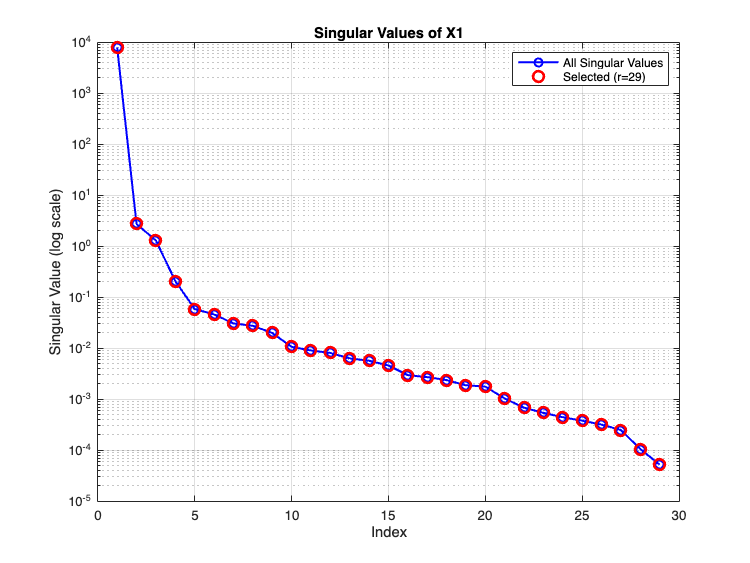

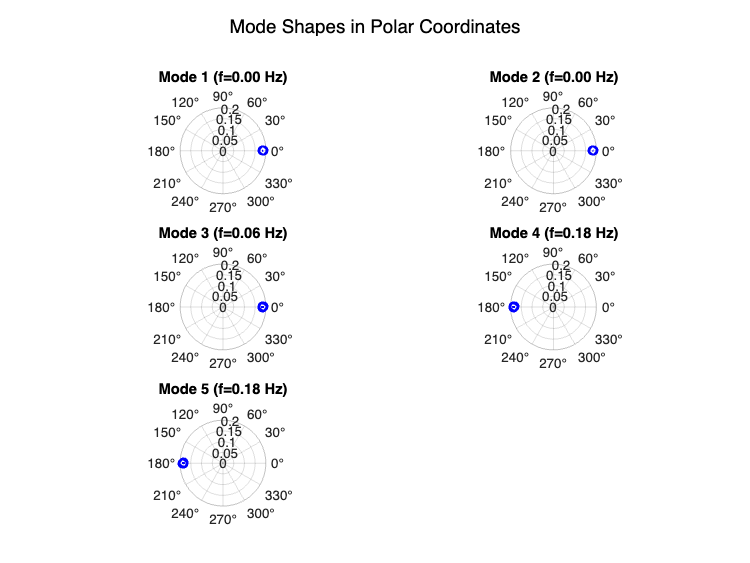

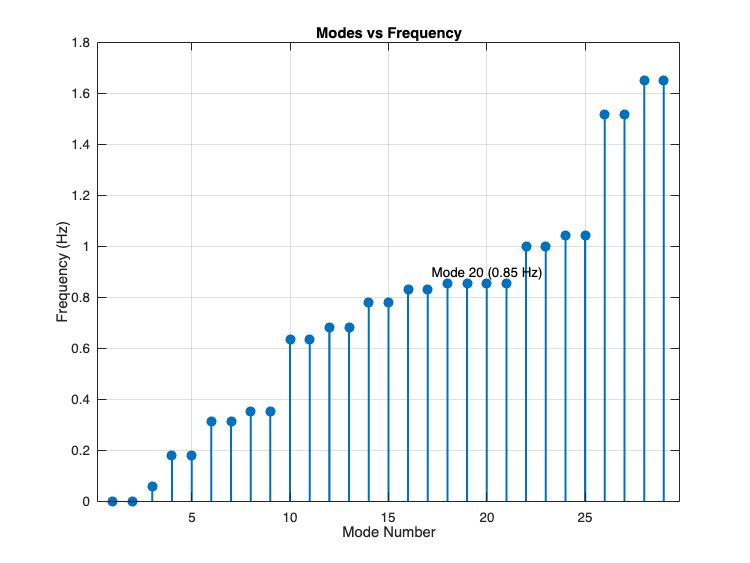


% --- Multi-Resolution DMD ---
try
    midpoint = floor(length(t)/2);
    r_mr = ceil(fixed_rank/2);
    % First temporal window
    X1_1 = Xraw(:, 1:midpoint); X2_1 = Xraw(:, 2:midpoint+1);
    % Second temporal window
    X1_2 = Xraw(:, midpoint:end-1); X2_2 = Xraw(:, midpoint+1:end);
    % SVD for each window
    [U1, S1, V1] = svd(X1_1, 'econ'); [U2, S2, V2] = svd(X1_2, 'econ');
    Ur1 = U1(:, 1:r_mr); Sr1 = S1(1:r_mr, 1:r_mr); Vr1 = V1(:, 1:r_mr);
    Ur2 = U2(:, 1:r_mr); Sr2 = S2(1:r_mr, 1:r_mr); Vr2 = V2(:, 1:r_mr);
    % Compute DMD operators
    Atilde1 = Ur1' * X2_1 * Vr1 / Sr1; Atilde2 = Ur2' * X2_2 * Vr2 / Sr2;
    Atilde1_reg = Atilde1 + reg_param * eye(size(Atilde1));
    Atilde2_reg = Atilde2 + reg_param * eye(size(Atilde2));
    % Eigenvalue decomposition
    [Phi1, Lambda1] = eig(Atilde1_reg); [Phi2, Lambda2] = eig(Atilde2_reg);
    Phi1 = Ur1 * Phi1; Phi2 = Ur2 * Phi2;
    % Combine modes and eigenvalues
    lambda_mr = [diag(Lambda1); diag(Lambda2)];
    Phi_mr = [Phi1, Phi2];
    % Truncate to fixed_rank if necessary
    if length(lambda_mr) > fixed_rank
        lambda_mr = lambda_mr(1:fixed_rank);
        Phi_mr = Phi_mr(:, 1:fixed_rank);
    end
    b_mr = pinv(Phi_mr) * Xraw(:, 1); % Mode amplitudes
    % Dimension checks
    assert(size(Phi_mr, 2) == length(b_mr), 'Multi-Resolution DMD: Phi and b dimensions mismatch');
    assert(length(b_mr) == length(lambda_mr), 'Multi-Resolution DMD: b and lambda dimensions mismatch');
    % Reconstruct data
    X_recon_mr = zeros(size(Xraw));
    for k = 1:length(t)
        X_recon_mr(:, k) = real(Phi_mr * (b_mr .* lambda_mr.^(k-1)));
    end
    error_mr = norm(Xraw - X_recon_mr, 'fro') / norm(Xraw, 'fro');
    % Analyze modes
    mode_props_mr = analyze_modes(Phi_mr, lambda_mr, abs(imag(log(lambda_mr)/dt))/(2*pi), ...
        -real(log(lambda_mr)/dt)./abs(log(lambda_mr)/dt), b_mr, num_gens);
catch e
    fprintf('Error in Multi-Resolution DMD: %s\n', e.message);
    error_mr = NaN;
    mode_props_mr = [];
end

% --- Display Modes and Plots ---
if ~isnan(error_mr) && ~isempty(mode_props_mr) && height(mode_props_mr) > 0
    fprintf('\n--- Multi-Resolution DMD ---\n');
    fprintf('Reconstruction Error: %.6e\n', error_mr);
    fprintf('Modes (%d total):\n', height(mode_props_mr));
    
    % Compute dominant generators
    dominant_gen = zeros(height(mode_props_mr), 1);
    for j = 1:height(mode_props_mr)
        mode_shape = mode_props_mr.mode_shape{j}(1:num_gens);
        participation = calc_participation(mode_shape, num_gens);
        [~, max_gen] = max(participation);
        dominant_gen(j) = max_gen;
    end
    mode_props_mr.dominant_generator = dominant_gen;
    
    % Display table
    try
        disp(mode_props_mr(:, {'frequency', 'damping_ratio', 'energy', 'amplitude', 'dominant_generator'}));
    catch e
        fprintf('Error displaying table: %s\n', e.message);
    end
    
    % --- Plotting ---
    % Singular Values Plot
    try
        figure;
        semilogy(singular_values, 'bo-', 'LineWidth', 1.5);
        hold on;
        semilogy(singular_values(1:r), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
        title('Singular Values of X1', 'FontSize', 14);
        xlabel('Index', 'FontSize', 12);
        ylabel('Singular Value (log scale)', 'FontSize', 12);
        legend('All Singular Values', sprintf('Selected (r=%d)', r));
        grid on;
        set(gca, 'FontSize', 10);
    catch e
        fprintf('Error in singular values plot: %s\n', e.message);
    end
    
    % Mode Shapes in Polar Coordinates (first few modes)
    try
        num_modes_to_plot = min(5, height(mode_props_mr)); % Plot up to 5 modes
        figure;
        for j = 1:num_modes_to_plot
            subplot(ceil(num_modes_to_plot/2), 2, j);
            mode_shape = mode_props_mr.mode_shape{j}(1:num_gens);
            theta = angle(mode_shape); % Phase in radians
            rho = abs(mode_shape); % Magnitude
            polarplot(theta, rho, 'bo-', 'LineWidth', 1.5);
            title(sprintf('Mode %d (f=%.2f Hz)', j, mode_props_mr.frequency(j)), 'FontSize', 10);
            pax = gca;
            pax.ThetaAxisUnits = 'degrees';
            pax.FontSize = 10;
        end
        sgtitle('Mode Shapes in Polar Coordinates', 'FontSize', 14);
    catch e
        fprintf('Error in mode shapes plot: %s\n', e.message);
    end
    
    % Modes vs Frequency Plot
    try
        figure;
        mode_numbers = 1:height(mode_props_mr);
        stem(mode_numbers, mode_props_mr.frequency, 'filled', 'LineWidth', 1.5, 'MarkerSize', 6);
        title('Modes vs Frequency', 'FontSize', 14);
        xlabel('Mode Number', 'FontSize', 12);
        ylabel('Frequency (Hz)', 'FontSize', 12);
        grid on;
        % Label the mode closest to 0.86 Hz
        [~, idx_086] = min(abs(mode_props_mr.frequency - 0.86));
        text(mode_numbers(idx_086), mode_props_mr.frequency(idx_086)*1.05, ...
             sprintf('Mode %d (%.2f Hz)', idx_086, mode_props_mr.frequency(idx_086)), ...
             'FontSize', 10, 'HorizontalAlignment', 'center');
        set(gca, 'FontSize', 10);
    catch e
        fprintf('Error in modes vs frequency plot: %s\n', e.message);
    end
else
    fprintf('\n--- Multi-Resolution DMD ---\n');
    fprintf('Failed to compute modes.\n');
end


% --- Helper Functions ---

function [Xraw, num_gens] = load_data(data_folder, dt)
    file_names = {'rotor_speeds.csv', 'rotor_angles.csv'};
    Xraw = [];
    num_gens = 0;
    
    for i = 1:length(file_names)
        file_path = fullfile(data_folder, file_names{i});
        if exist(file_path, 'file')
            data = readmatrix(file_path, 'NumHeaderLines', 1);
            if size(data, 2) < 2
                warning('File %s has insufficient columns.', file_names{i});
                continue;
            end
            data = data(:, 2:end);
            fprintf('Raw data size for %s: %d rows, %d columns\n', file_names{i}, size(data, 1), size(data, 2));
            if contains(file_names{i}, 'rotor_speeds', 'IgnoreCase', true)
                num_gens = size(data, 2);
                mean_spd = mean(data(:));
                if mean_spd < 1
                    warning('Rotor speeds appear to be in per-unit (mean = %.4f). Converting to Hz assuming 60 Hz base.', mean_spd);
                    data = data * 60;
                end
            else
                max_val = max(abs(data(:)));
                if max_val > 0
                    data = data / max_val;
                else
                    data = zeros(size(data));
                end
            end
            Xraw = [Xraw; data];
            fprintf('Loaded %s: %d rows, %d columns\n', file_names{i}, size(data, 1), size(data, 2));
        else
            warning('File %s not found.', file_path);
        end
    end
    
    if isempty(Xraw)
        error('No data loaded.');
    end
    
    Xraw = Xraw';
    fprintf('Final Xraw: %d signals, %d time steps\n', size(Xraw, 1), size(Xraw, 2));
end

function mode_props = analyze_modes(Phi, lambda, freq_Hz, damping_ratio, b, num_gens)
    num_modes = length(lambda);
    mode_energy = abs(b).^2;
    amplitude = abs(b); % Amplitude is the magnitude of b
    
    mode_shapes = cell(num_modes, 1);
    for i = 1:num_modes
        mode_shapes{i} = Phi(:, i);
    end
    
    mode_props = table(...
        freq_Hz(:), damping_ratio(:), mode_energy(:), amplitude(:), mode_shapes, ...
        'VariableNames', {'frequency', 'damping_ratio', 'energy', 'amplitude', 'mode_shape'});
    
    mode_props = sortrows(mode_props, 'frequency');
end

function participation = calc_participation(mode_shape, num_gens)
    if length(mode_shape) < num_gens
        error('Mode shape length (%d) less than num_gens (%d).', length(mode_shape), num_gens);
    end
    mode = mode_shape(1:num_gens);
    norm_val = norm(mode);
    if norm_val > 1e-6
        normalized = mode / norm_val;
    else
        normalized = zeros(size(mode));
    end
    participation = abs(normalized).^2;
end